## Generate artificial data

clear all;

x = -4:0.05:4;
y = -4:0.05:4;

rng(123456);

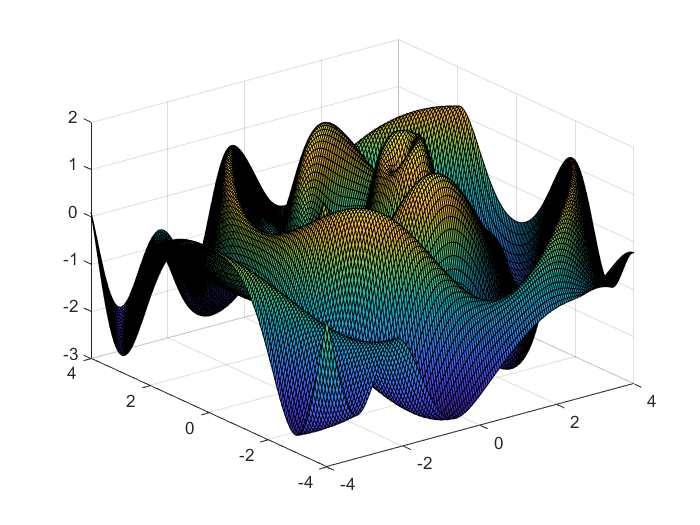

figure;
[X, Y] = meshgrid(x, y);
fkk = 2; % frequency of test function
freq=2*fkk; fk=1;
f1 = @(x,y) sin(freq*sqrt((x-fk).^2+y.^2));%./(freq*sqrt((x-fk).^2+y.^2));
freq=1*fkk; fk=-1;
f2 = @(x,y) -sin(freq*sqrt((x-fk).^2+y.^2));%./(freq*sqrt((x-fk).^2+y.^2));
freq = 0.1*fkk;
f3 = @(x,y) -sin(freq*sqrt(x.^2+y.^2));
ff = @(x,y) f1(x,y)+f2(x,y)+f3(x,y);
Z = ff(X, Y);
%Z = peaks(X, Y);
surf(X, Y, Z);

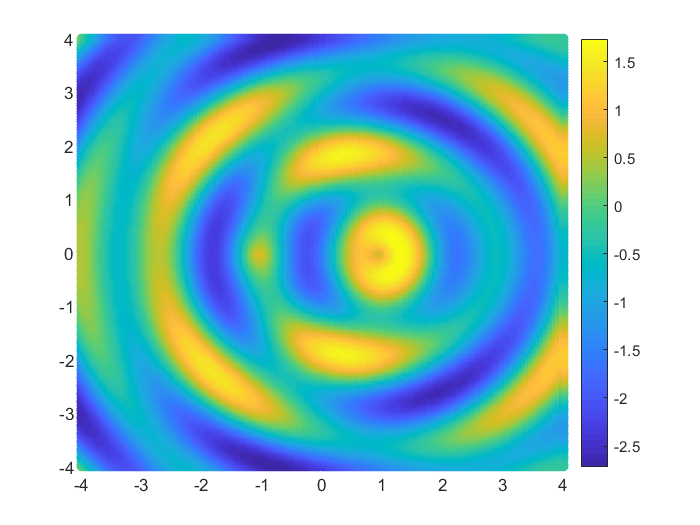

figure;
scatter(X(:), Y(:), [], Z(:), "filled");
colorbar;

xnorm = 1; ynorm = 1; % whether use normalization
yns = 0.1; % noise scale

n = 1e4; % size of training data
ttcs = 300;
ttm = round(n / (ttcs/2));

% represent_ratio = 5;
% dcs = 300; % size of the communication set
% mn = round(n / dcs); % mn is the number of experts (normal)
% m = round(n / (dcs*represent_ratio)); % m is the number of experts (sparse representative)
% lamds = 0:0.5:3.0;

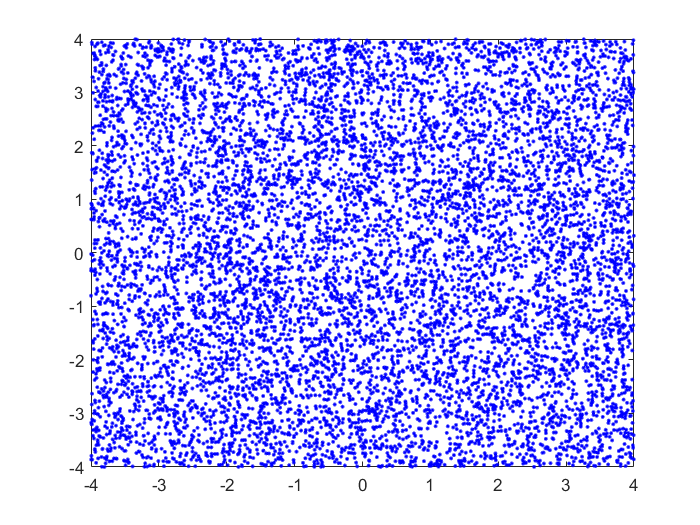

testsize = 2000; % size of test data
valsize = 1000;
induce_step = 100;

% training input
ori_all_trainxs = 8*(rand(n, 1)-0.5);
ori_all_trainys = 8*(rand(n, 1)-0.5);

figure;
plot(ori_all_trainxs, ori_all_trainys, 'b.');

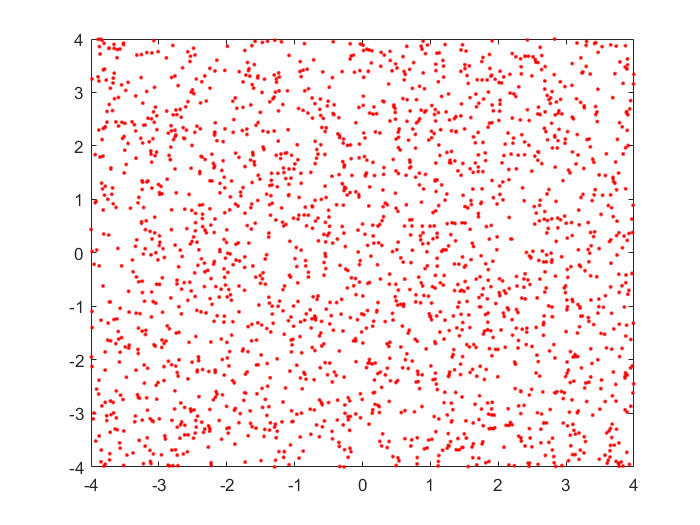


% test input
ori_testxs = 8*(rand(testsize, 1)-0.5);
ori_testys = 8*(rand(testsize, 1)-0.5);

% validation input
ori_valxs = 8*(rand(valsize, 1)-0.5);
ori_valys = 8*(rand(valsize, 1)-0.5);

figure;
plot(ori_testxs, ori_testys, 'r.');


% ininput normalization
if xnorm == 1
    norm_xmean = mean(ori_all_trainxs);
    norm_xstd = std(ori_all_trainxs);
    all_trainxs = (ori_all_trainxs - norm_xmean) / norm_xstd;
    norm_ymean = mean(ori_all_trainys);
    norm_ystd = std(ori_all_trainys);
    all_trainys = (ori_all_trainys - norm_ymean) / norm_ystd;
    
    testxs = (ori_testxs - norm_xmean) / norm_xstd;
    testys = (ori_testys - norm_ymean) / norm_ystd;
    
    valxs = (ori_valxs - norm_xmean) / norm_xstd;
    valys = (ori_valys - norm_ymean) / norm_ystd;
else
    all_trainxs = ori_all_trainxs;
    all_trainys = ori_all_trainys;
    testxs = ori_testxs;
    testys = ori_testys;    
    valxs = ori_valxs;
    valys = ori_valys;    
end

% training output
ln = length(all_trainxs);
xvec = zeros(ln, 2); ori_xvec = zeros(ln, 2);
for i = 1:ln
    xvec(i, :) = [all_trainxs(i), all_trainys(i)];
    ori_xvec(i, :) = [ori_all_trainxs(i), ori_all_trainys(i)];
end
ori_yvec = ff(ori_all_trainxs, ori_all_trainys) + yns*randn(ln, 1);

% test output
ln = length(testxs);
xvec_test = zeros(ln, 2); ori_xvec_test = zeros(ln, 2);
for i = 1:ln
    xvec_test(i, :) = [testxs(i), testys(i)];
    ori_xvec_test(i, :) = [ori_testxs(i), ori_testys(i)];
end
ori_yvec_test = ff(ori_testxs, ori_testys) + yns*randn(ln, 1);

% validation output
ln = length(valxs);
xvec_val = zeros(ln, 2); ori_xvec_val = zeros(ln, 2);
for i = 1:ln
    xvec_val(i, :) = [valxs(i), valys(i)];
    ori_xvec_val(i, :) = [ori_valxs(i), ori_valys(i)];
end
ori_yvec_val = ff(ori_valxs, ori_valys) + yns*randn(ln, 1);

% output normalization
if ynorm == 1
    norm_fmean = mean(ori_yvec);
    norm_fstd = std(ori_yvec);
    all_trainxs = (ori_all_trainxs - norm_xmean) / norm_xstd;
    yvec = (ori_yvec - norm_fmean) / norm_fstd;
    yvec_test = (ori_yvec_test - norm_fmean) / norm_fstd;
    yvec_val = (ori_yvec_val - norm_fmean) / norm_fstd;
else
    yvec = ori_yvec;
    yvec_test = ori_yvec_test;
    yvec_val = ori_yvec_val;
end

store results

kti = 5; % average over kti runs
grls = 0.3:0.05:1.0; % percentage of remaining data to be test
grbcm0_smse_rec = zeros(kti, 1);
rbcm0_smse_rec = zeros(kti, 1);
bcm0_smse_rec = zeros(kti, 1);
gpoe0_smse_rec = zeros(kti, 1);
poe0_smse_rec = zeros(kti, 1);
vfe0_smse_rec = zeros(kti, 1);
spgp0_smse_rec = zeros(kti, 1);
grbcm0_msll_rec = zeros(kti, 1);
rbcm0_msll_rec = zeros(kti, 1);
bcm0_msll_rec = zeros(kti, 1);
gpoe0_msll_rec = zeros(kti, 1);
poe0_msll_rec = zeros(kti, 1);
vfe0_msll_rec = zeros(kti, 1);
spgp0_msll_rec = zeros(kti, 1);
grbcm_gr_smse = zeros(kti, length(grls));
grbcm_gr_msll = zeros(kti, length(grls));
grbcm2_gr_smse = zeros(kti, length(grls));
grbcm2_gr_msll = zeros(kti, length(grls));
grbcm2_spgp_gr_smse = zeros(kti, length(grls));
grbcm2_spgp_gr_msll = zeros(kti, length(grls));

## Experiment I: remove data from the training set

sf2 = 1 ; ell = 1 ; sn2 = 0.1 ; 
d = size(xvec,2);
opts.Xnorm = 'N' ; opts.Ynorm = 'N' ;
opts.Ms = ttm+1;
opts.ell = ell ; opts.sf2 = sf2 ; opts.sn2 = sn2 ;
opts.meanfunc = []; opts.covfunc = @covSEard; opts.likfunc = @likGauss; opts.inffunc = @infGaussLik ;

meanfunc = [];                    % empty: don't use a mean function
covfunc = opts.covfunc;              % Squared Exponental covariance function
likfunc = opts.likfunc;              % Gaussian likelihood
inffunc = opts.inffunc;
km_iters = 1e4;
opts.induce_step = induce_step ;

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 50 ;
opts.Ms = ttm+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, []};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

% default partition
dcs_ecs_r = 0.5;
dcs = round(ttcs*dcs_ecs_r) % size of the communication set

dcs = 150

ecs = ttcs - dcs % size of other experts

ecs = 150

n_per = dcs ; % size of Dc
mn = round(n / ecs); % mn is the number of experts (normal)
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, mn,'MaxIter',km_iters);    

Baselines of VFE and SPGP.

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = mn+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 1;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 

Optimizing hyps in training...
Linesearch      0;  Value 5.162781e+03
Linesearch      1;  Value 2.449878e+03
Linesearch      2;  Value -1.331980e+03
Linesearch      3;  Value -5.249277e+03
Linesearch      4;  Value -5.962682e+03
Linesearch      5;  Value -6.032907e+03
Linesearch      6;  Value -6.069304e+03
Linesearch      7;  Value -6.274396e+03
Linesearch      8;  Value -6.315859e+03
Linesearch      9;  Value -6.320591e+03
Linesearch     10;  Value -6.322875e+03
Linesearch     11;  Value -6.323489e+03
Linesearch     12;  Value -6.324257e+03
Linesearch     13;  Value -6.325137e+03
Linesearch     14;  Value -6.325151e+03
Linesearch     15;  Value -6.325154e+03
Linesearch     16;  Value -6.325154e+03
Linesearch     17;  Value -6.325155e+03
Linesearch     18;  Value -6.325155e+03
Linesearch     19;  Value -6.325155e+03
Linesearch     20;  Value -6.325155e+03
Linesearch     21;  Value -6.325155e+03
Linesearch     22;  Value -6.325155e+03
Linesearch     23;  Value -6.325155e+03
Linesearch 

opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_test,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);

GRBCM (Dc size 150): MSE 0.01179634, SMSE 0.01238287, MSLL -2.04868360



g_opts.compute_hyp = 0;

When testing baseline, VFE and SPGP use all partition budget (ttcs = dcs + ecs).

I_com2 = Indics(1:ttcs) ; % randomly select communication set

% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com2, :);
inffunc = @(varargin) infGaussLik(varargin{:}, struct('s', 0.0));
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
[vfe_hyp, tmp_nlzs] = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);

Function evaluation      0;  Value 6.697854e+02
Function evaluation     10;  Value -8.441569e+02
Function evaluation     13;  Value -2.343632e+03
Function evaluation     14;  Value -4.484990e+03
Function evaluation     15;  Value -4.940360e+03
Function evaluation     18;  Value -5.556287e+03
Function evaluation     19;  Value -6.084505e+03
Function evaluation     21;  Value -6.381782e+03
Function evaluation     23;  Value -6.572633e+03
Function evaluation     24;  Value -6.739983e+03
Function evaluation     27;  Value -6.819390e+03
Function evaluation     28;  Value -6.895779e+03
Function evaluation     30;  Value -6.933462e+03
Function evaluation     32;  Value -6.952915e+03
Function evaluation     35;  Value -6.980646e+03
Function evaluation     37;  Value -6.998711e+03
Function evaluation     39;  Value -7.014689e+03
Function evaluation     41;  Value -7.025193e+03
Function evaluation     43;  Value -7.032373e+03
Function evaluation     45;  Value -7.038789e+03
Function evaluation  

vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_test);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE,vfeSMSE,vfeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE baseline', n_per, vfeMSE,vfeSMSE,vfeMSLL);

VFE baseline (Dc size 150): MSE 0.01095326, SMSE 0.01149786, MSLL -2.22928219


% vfe0_smse_rec(ki) = vfeSMSE; vfe0_msll_rec(ki) = vfeMSLL;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

sp_opts = opts;
sp_opts.induce_size = ttcs;
sp_opts.induce_type = 'SPGP_opt';
hyp_init(1:d,1) = -2*opts.hyp.cov(1:d);
hyp_init(d+1,1) = 2*opts.hyp.cov(d+1);
hyp_init(d+2,1) = 2*opts.hyp.lik;

xu = xvec(I_com2, :);
w_init = [reshape(xu,sp_opts.induce_size*d,1);hyp_init];
[w,tmp_nlzs] = minimize(w_init,'spgp_lik_nohyp',-sp_opts.induce_step,yvec,xvec,sp_opts.induce_size);

Function evaluation      0;  Value -6.615935e+03
Function evaluation      8;  Value -6.773176e+03
Function evaluation     10;  Value -7.129234e+03
Function evaluation     12;  Value -7.258895e+03
Function evaluation     16;  Value -7.359168e+03
Function evaluation     18;  Value -7.453648e+03
Function evaluation     19;  Value -7.520448e+03
Function evaluation     21;  Value -7.564845e+03
Function evaluation     23;  Value -7.587883e+03
Function evaluation     26;  Value -7.617321e+03
Function evaluation     29;  Value -7.624374e+03
Function evaluation     31;  Value -7.638049e+03
Function evaluation     33;  Value -7.645932e+03
Function evaluation     35;  Value -7.658067e+03
Function evaluation     37;  Value -7.662863e+03
Function evaluation     39;  Value -7.663976e+03
Function evaluation     42;  Value -7.669416e+03
Function evaluation     46;  Value -7.670158e+03
Function evaluation     50;  Value -7.680442e+03
Function evaluation     53;  Value -7.681455e+03
Function evaluation 

xb = reshape(w(1:sp_opts.induce_size*d,1),sp_opts.induce_size,d);
sp_opts.xu = xb;
sp_opts.sp_hyp = w(sp_opts.induce_size*d+1:end,1);
sp_opts.hyp = opts.hyp;
[tmu,ts2] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,xvec_test,sp_opts.sp_hyp);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[spgpMSE,spgpSMSE,spgpMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'SPSG baseline', n_per, spgpMSE,spgpSMSE,spgpMSLL);

SPSG baseline (Dc size 150): MSE 0.01103506, SMSE 0.01158373, MSLL -2.21967138


% spgp0_smse_rec(ki) = spgpSMSE; spgp0_msll_rec(ki) = spgpMSLL;
[yu,su] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,sp_opts.xu,sp_opts.sp_hyp);
sp_opts.yu = yu; sp_opts.su = su;

Average over 5 runs.

==============1================

Optimizing hyps in training...
Linesearch      0;  Value 5.385029e+03
Linesearch      1;  Value 3.234932e+03
Linesearch      2;  Value -2.707768e+02
Linesearch      3;  Value -5.190398e+03
Linesearch      4;  Value -5.965677e+03
Linesearch      5;  Value -6.046373e+03
Linesearch      6;  Value -6.226080e+03
Linesearch      7;  Value -6.329636e+03
Linesearch      8;  Value -6.371351e+03
Linesearch      9;  Value -6.373932e+03
Linesearch     10;  Value -6.374328e+03
Linesearch     11;  Value -6.374465e+03
Linesearch     12;  Value -6.374489e+03
Linesearch     13;  Value -6.374495e+03
Linesearch     14;  Value -6.374495e+03
Linesearch     15;  Value -6.374495e+03
Linesearch     16;  Value -6.374495e+03
Linesearch     17;  Value -6.374495e+03
Linesearch     18;  Value -6.374495e+03
Linesearch     19;  Value -6.374495e+03
Linesearch     20;  Value -6.374495e+03
Linesearch     21;  Value -6.374495e+03
Linesearch     22;  Value -6.374495e+03
Linesearch     23;  Value -6.374495e+03
Linesearch 

GRBCM (Dc size 150): MSE 0.01139128, SMSE 0.01195766, MSLL -2.08934137


Function evaluation      0;  Value 8.367137e+04
Function evaluation     13;  Value 6.853488e+04
Function evaluation     14;  Value 4.447068e+04
Function evaluation     16;  Value 3.114094e+04
Function evaluation     18;  Value 2.511706e+04
Function evaluation     20;  Value 2.221299e+04
Function evaluation     22;  Value 1.972557e+04
Function evaluation     24;  Value 1.818714e+04
Function evaluation     26;  Value 1.731422e+04
Function evaluation     28;  Value 1.678572e+04
Function evaluation     29;  Value 1.622786e+04
Function evaluation     31;  Value 1.576174e+04
Function evaluation     33;  Value 1.537683e+04
Function evaluation     35;  Value 1.505397e+04
Function evaluation     36;  Value 1.473428e+04
Function evaluation     38;  Value 1.460210e+04
Function evaluation     39;  Value 1.446488e+04
Function evaluation     41;  Value 1.436124e+04
Function evaluation     43;  Value 1.430701e+04
Function evaluation     45;  Value 1.424575e+04
Function evaluation     46;  Value 1.418

VFE (Dc size 150): MSE 0.01369386, SMSE 0.01437472, MSLL -1.86004928


Function evaluation      0;  Value 1.441805e+02
Function evaluation     10;  Value -8.265688e+02
Function evaluation     13;  Value -1.715202e+03
Function evaluation     14;  Value -2.269937e+03
Function evaluation     16;  Value -2.640938e+03
Function evaluation     18;  Value -3.000908e+03
Function evaluation     20;  Value -3.304308e+03
Function evaluation     22;  Value -3.546761e+03
Function evaluation     24;  Value -3.722466e+03
Function evaluation     26;  Value -3.829921e+03
Function evaluation     28;  Value -3.912823e+03
Function evaluation     29;  Value -3.994168e+03
Function evaluation     31;  Value -4.049572e+03
Function evaluation     32;  Value -4.105239e+03
Function evaluation     34;  Value -4.144733e+03
Function evaluation     35;  Value -4.185232e+03
Function evaluation     37;  Value -4.220547e+03
Function evaluation     39;  Value -4.242051e+03
Function evaluation     41;  Value -4.247524e+03
Function evaluation     43;  Value -4.261855e+03
Function evaluation  

SPSG (Dc size 150): MSE 0.02530876, SMSE 0.02656713, MSLL -1.84315299


GRBCM (VFE) (Dc size 150): MSE 0.01095005, SMSE 0.01149450, MSLL -2.20379153


GRBCM (SPGP) (Dc size 150): MSE 0.01140266, SMSE 0.01196961, MSLL -2.15665419


RBCM (Dc size 150): MSE 0.01159382, SMSE 0.0122, MSLL -1.5360


BCM (Dc size 150): MSE 0.01207724, SMSE 0.0127, MSLL -2.0767


PoE (Dc size 150): MSE 0.08200900, SMSE 0.0861, MSLL 4.9382


GPoE (Dc size 150): MSE 0.01182763, SMSE 0.0124, MSLL -1.4719


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

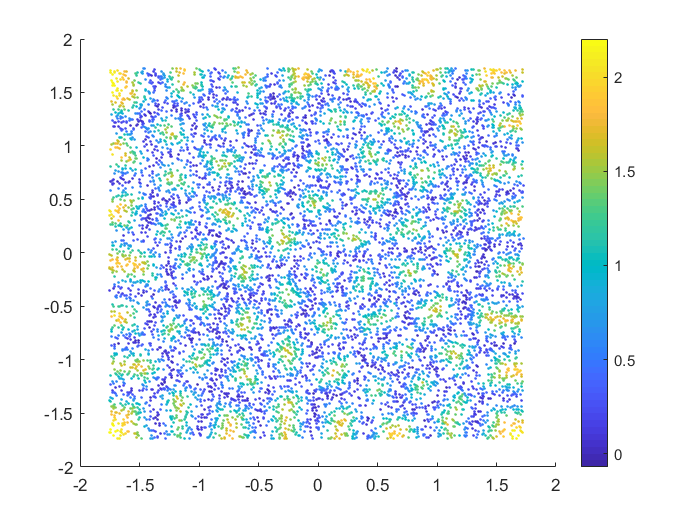

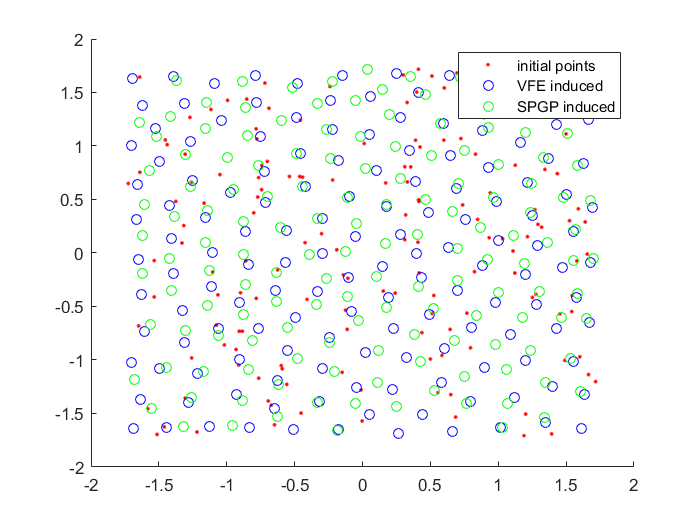

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.01739541, SMSE 0.0183, MSLL -2.0064


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01254776, SMSE 0.0132, MSLL -2.1049


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01291186, SMSE 0.0136, MSLL -2.0967


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.01564784, SMSE 0.0164, MSLL -2.0501


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01243585, SMSE 0.0131, MSLL -2.1266


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01238654, SMSE 0.0130, MSLL -2.1220


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.01457483, SMSE 0.0153, MSLL -2.0805


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01219412, SMSE 0.0128, MSLL -2.1488


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01205852, SMSE 0.0127, MSLL -2.1457


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01389724, SMSE 0.0146, MSLL -2.1011


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01191639, SMSE 0.0125, MSLL -2.1686


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01181586, SMSE 0.0124, MSLL -2.1611


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01343202, SMSE 0.0141, MSLL -2.1106


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01181086, SMSE 0.0124, MSLL -2.1800


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01168053, SMSE 0.0123, MSLL -2.1720


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01270172, SMSE 0.0133, MSLL -2.1330


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01157062, SMSE 0.0121, MSLL -2.1918


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01139965, SMSE 0.0120, MSLL -2.1861


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01259985, SMSE 0.0132, MSLL -2.1247


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01157882, SMSE 0.0122, MSLL -2.1942


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01135532, SMSE 0.0119, MSLL -2.1907


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01234027, SMSE 0.0130, MSLL -2.1193


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01152467, SMSE 0.0121, MSLL -2.1965


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01148786, SMSE 0.0121, MSLL -2.1844


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01211184, SMSE 0.0127, MSLL -2.1235


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01140105, SMSE 0.0120, MSLL -2.1995


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01149870, SMSE 0.0121, MSLL -2.1813


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01196623, SMSE 0.0126, MSLL -2.1149


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01138711, SMSE 0.0120, MSLL -2.1971


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01156105, SMSE 0.0121, MSLL -2.1743


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01170724, SMSE 0.0123, MSLL -2.1174


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01129221, SMSE 0.0119, MSLL -2.1983


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01159206, SMSE 0.0122, MSLL -2.1661


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01165361, SMSE 0.0122, MSLL -2.1041


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01123925, SMSE 0.0118, MSLL -2.1983


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01155159, SMSE 0.0121, MSLL -2.1625


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01153679, SMSE 0.0121, MSLL -2.1005


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01113399, SMSE 0.0117, MSLL -2.2009


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01151773, SMSE 0.0121, MSLL -2.1600


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01153869, SMSE 0.0121, MSLL -2.0857


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01109318, SMSE 0.0116, MSLL -2.1985


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01153632, SMSE 0.0121, MSLL -2.1513


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01139128, SMSE 0.0120, MSLL -2.0893


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01095005, SMSE 0.0115, MSLL -2.2038


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01140266, SMSE 0.0120, MSLL -2.1567


==============2================

Optimizing hyps in training...
Linesearch      0;  Value 5.638740e+03
Linesearch      1;  Value 3.605276e+03
Linesearch      2;  Value -6.005281e+02
Linesearch      3;  Value -4.724894e+03
Linesearch      4;  Value -5.926020e+03
Linesearch      5;  Value -5.970024e+03
Linesearch      6;  Value -6.050656e+03
Linesearch      7;  Value -6.173519e+03
Linesearch      8;  Value -6.285687e+03
Linesearch      9;  Value -6.328349e+03
Linesearch     10;  Value -6.329906e+03
Linesearch     11;  Value -6.331703e+03
Linesearch     12;  Value -6.333470e+03
Linesearch     13;  Value -6.334108e+03
Linesearch     14;  Value -6.334721e+03
Linesearch     15;  Value -6.334746e+03
Linesearch     16;  Value -6.334751e+03
Linesearch     17;  Value -6.334752e+03
Linesearch     18;  Value -6.334753e+03
Linesearch     19;  Value -6.334754e+03
Linesearch     20;  Value -6.334755e+03
Linesearch     21;  Value -6.334755e+03
Linesearch     22;  Value -6.334755e+03
Linesearch     23;  Value -6.334755e+03
Linesearch 

GRBCM (Dc size 150): MSE 0.01163393, SMSE 0.01221238, MSLL -2.02731277


Function evaluation      0;  Value 1.073122e+05
Function evaluation     12;  Value 9.321011e+04
Function evaluation     14;  Value 6.269181e+04
Function evaluation     17;  Value 4.860754e+04
Function evaluation     19;  Value 3.865753e+04
Function evaluation     21;  Value 3.284925e+04
Function evaluation     23;  Value 2.909480e+04
Function evaluation     25;  Value 2.581498e+04
Function evaluation     27;  Value 2.369526e+04
Function evaluation     29;  Value 2.213212e+04
Function evaluation     31;  Value 2.113722e+04
Function evaluation     33;  Value 2.024226e+04
Function evaluation     35;  Value 1.967130e+04
Function evaluation     37;  Value 1.918537e+04
Function evaluation     39;  Value 1.884627e+04
Function evaluation     41;  Value 1.842534e+04
Function evaluation     43;  Value 1.808744e+04
Function evaluation     45;  Value 1.780546e+04
Function evaluation     47;  Value 1.760369e+04
Function evaluation     49;  Value 1.731485e+04
Function evaluation     51;  Value 1.710

VFE (Dc size 150): MSE 0.01421180, SMSE 0.01491842, MSLL -1.82636187


Function evaluation      0;  Value 7.511621e+02
Function evaluation     10;  Value -5.742617e+02
Function evaluation     11;  Value -1.396250e+03
Function evaluation     13;  Value -1.954734e+03
Function evaluation     16;  Value -2.326029e+03
Function evaluation     19;  Value -2.709197e+03
Function evaluation     21;  Value -3.018381e+03
Function evaluation     24;  Value -3.078099e+03
Function evaluation     26;  Value -3.264271e+03
Function evaluation     28;  Value -3.444762e+03
Function evaluation     30;  Value -3.558030e+03
Function evaluation     32;  Value -3.629687e+03
Function evaluation     34;  Value -3.714286e+03
Function evaluation     36;  Value -3.776445e+03
Function evaluation     38;  Value -3.813070e+03
Function evaluation     39;  Value -3.847079e+03
Function evaluation     41;  Value -3.872985e+03
Function evaluation     43;  Value -3.895947e+03
Function evaluation     45;  Value -3.911625e+03
Function evaluation     47;  Value -3.923151e+03
Function evaluation  

SPSG (Dc size 150): MSE 0.02292318, SMSE 0.02406293, MSLL -1.81821628


GRBCM (VFE) (Dc size 150): MSE 0.01119413, SMSE 0.01175071, MSLL -2.18946377


GRBCM (SPGP) (Dc size 150): MSE 0.01124675, SMSE 0.01180595, MSLL -2.17114343


RBCM (Dc size 150): MSE 0.01185232, SMSE 0.0124, MSLL -1.5092


BCM (Dc size 150): MSE 0.01226770, SMSE 0.0129, MSLL -2.0627


PoE (Dc size 150): MSE 0.08605954, SMSE 0.0903, MSLL 5.2101


GPoE (Dc size 150): MSE 0.01193050, SMSE 0.0125, MSLL -1.4729


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.01710950, SMSE 0.0180, MSLL -1.9981


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01206910, SMSE 0.0127, MSLL -2.1174


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01253507, SMSE 0.0132, MSLL -2.1047


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.01597488, SMSE 0.0168, MSLL -2.0242


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01186532, SMSE 0.0125, MSLL -2.1436


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01270068, SMSE 0.0133, MSLL -2.1099


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.01525040, SMSE 0.0160, MSLL -2.0413


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01178270, SMSE 0.0124, MSLL -2.1624


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01269104, SMSE 0.0133, MSLL -2.1184


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01441597, SMSE 0.0151, MSLL -2.0600


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01161554, SMSE 0.0122, MSLL -2.1788


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01242633, SMSE 0.0130, MSLL -2.1324


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01388002, SMSE 0.0146, MSLL -2.0694


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01153083, SMSE 0.0121, MSLL -2.1911


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01230669, SMSE 0.0129, MSLL -2.1347


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01338500, SMSE 0.0141, MSLL -2.0763


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01169234, SMSE 0.0123, MSLL -2.1885


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01217082, SMSE 0.0128, MSLL -2.1420


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01285115, SMSE 0.0135, MSLL -2.0852


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01143049, SMSE 0.0120, MSLL -2.2015


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01175538, SMSE 0.0123, MSLL -2.1633


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01254187, SMSE 0.0132, MSLL -2.0879


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01135387, SMSE 0.0119, MSLL -2.2061


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01155790, SMSE 0.0121, MSLL -2.1752


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01230063, SMSE 0.0129, MSLL -2.0898


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01130950, SMSE 0.0119, MSLL -2.2073


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01147323, SMSE 0.0120, MSLL -2.1792


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01219888, SMSE 0.0128, MSLL -2.0756


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01135642, SMSE 0.0119, MSLL -2.2035


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01143491, SMSE 0.0120, MSLL -2.1808


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01218183, SMSE 0.0128, MSLL -2.0575


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01138244, SMSE 0.0119, MSLL -2.1988


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01150544, SMSE 0.0121, MSLL -2.1714


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01194258, SMSE 0.0125, MSLL -2.0588


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01129191, SMSE 0.0119, MSLL -2.2000


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01134323, SMSE 0.0119, MSLL -2.1792


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01174444, SMSE 0.0123, MSLL -2.0555


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01116425, SMSE 0.0117, MSLL -2.2019


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01121860, SMSE 0.0118, MSLL -2.1833


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01166532, SMSE 0.0122, MSLL -2.0405


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01116838, SMSE 0.0117, MSLL -2.1959


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01123717, SMSE 0.0118, MSLL -2.1764


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01163393, SMSE 0.0122, MSLL -2.0273


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01119413, SMSE 0.0118, MSLL -2.1895


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01124675, SMSE 0.0118, MSLL -2.1711


==============3================

Optimizing hyps in training...
Linesearch      0;  Value 5.386432e+03
Linesearch      1;  Value 2.984077e+03
Linesearch      2;  Value -9.523606e+02
Linesearch      3;  Value -5.161134e+03
Linesearch      4;  Value -5.971739e+03
Linesearch      5;  Value -6.004446e+03
Linesearch      6;  Value -6.146076e+03
Linesearch      7;  Value -6.269819e+03
Linesearch      8;  Value -6.292849e+03
Linesearch      9;  Value -6.305531e+03
Linesearch     10;  Value -6.308167e+03
Linesearch     11;  Value -6.310531e+03
Linesearch     12;  Value -6.310671e+03
Linesearch     13;  Value -6.310680e+03
Linesearch     14;  Value -6.310684e+03
Linesearch     15;  Value -6.310684e+03
Linesearch     16;  Value -6.310684e+03
Linesearch     17;  Value -6.310684e+03
Linesearch     18;  Value -6.310684e+03
Linesearch     19;  Value -6.310684e+03
Linesearch     20;  Value -6.310684e+03
Linesearch     21;  Value -6.310684e+03
Linesearch     22;  Value -6.310684e+03
Linesearch     23;  Value -6.310684e+03


GRBCM (Dc size 150): MSE 0.01158586, SMSE 0.01216192, MSLL -1.99965990


Function evaluation      0;  Value 1.080256e+05
Function evaluation     11;  Value 1.068845e+05
Function evaluation     16;  Value 9.061339e+04
Function evaluation     18;  Value 6.013886e+04
Function evaluation     21;  Value 4.948223e+04
Function evaluation     22;  Value 4.000395e+04
Function evaluation     24;  Value 3.485884e+04
Function evaluation     25;  Value 3.074590e+04
Function evaluation     27;  Value 2.699422e+04
Function evaluation     29;  Value 2.419657e+04
Function evaluation     31;  Value 2.251128e+04
Function evaluation     33;  Value 2.130937e+04
Function evaluation     34;  Value 2.015717e+04
Function evaluation     36;  Value 1.920895e+04
Function evaluation     38;  Value 1.843460e+04
Function evaluation     40;  Value 1.784670e+04
Function evaluation     42;  Value 1.731294e+04
Function evaluation     44;  Value 1.689626e+04
Function evaluation     45;  Value 1.651631e+04
Function evaluation     47;  Value 1.627488e+04
Function evaluation     49;  Value 1.605

VFE (Dc size 150): MSE 0.01338109, SMSE 0.01404641, MSLL -1.83488690


Function evaluation      0;  Value 6.146704e+02
Function evaluation      5;  Value 5.828182e+02
Function evaluation     11;  Value -3.320418e+02
Function evaluation     15;  Value -7.489599e+02
Function evaluation     16;  Value -1.281569e+03
Function evaluation     17;  Value -1.833580e+03
Function evaluation     19;  Value -2.280788e+03
Function evaluation     22;  Value -2.439660e+03
Function evaluation     24;  Value -2.824487e+03
Function evaluation     26;  Value -3.076901e+03
Function evaluation     28;  Value -3.279065e+03
Function evaluation     30;  Value -3.433164e+03
Function evaluation     32;  Value -3.539743e+03
Function evaluation     34;  Value -3.602123e+03
Function evaluation     35;  Value -3.663897e+03
Function evaluation     37;  Value -3.707388e+03
Function evaluation     39;  Value -3.738265e+03
Function evaluation     41;  Value -3.767340e+03
Function evaluation     43;  Value -3.802769e+03
Function evaluation     45;  Value -3.826875e+03
Function evaluation   

SPSG (Dc size 150): MSE 0.02339898, SMSE 0.02456240, MSLL -1.81421902


GRBCM (VFE) (Dc size 150): MSE 0.01109536, SMSE 0.01164703, MSLL -2.18553293


GRBCM (SPGP) (Dc size 150): MSE 0.01105575, SMSE 0.01160545, MSLL -2.18009869


RBCM (Dc size 150): MSE 0.01166361, SMSE 0.0122, MSLL -1.5217


BCM (Dc size 150): MSE 0.01211051, SMSE 0.0127, MSLL -2.0758


PoE (Dc size 150): MSE 0.07710818, SMSE 0.0809, MSLL 4.2973


GPoE (Dc size 150): MSE 0.01170504, SMSE 0.0123, MSLL -1.4961


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.01834617, SMSE 0.0193, MSLL -1.9849


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01270275, SMSE 0.0133, MSLL -2.1068


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01259191, SMSE 0.0132, MSLL -2.1065


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.01595394, SMSE 0.0167, MSLL -2.0405


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01239972, SMSE 0.0130, MSLL -2.1355


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01221854, SMSE 0.0128, MSLL -2.1342


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.01487661, SMSE 0.0156, MSLL -2.0650


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01216192, SMSE 0.0128, MSLL -2.1562


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01211535, SMSE 0.0127, MSLL -2.1486


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01422002, SMSE 0.0149, MSLL -2.0749


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01201862, SMSE 0.0126, MSLL -2.1690


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01207273, SMSE 0.0127, MSLL -2.1572


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01352306, SMSE 0.0142, MSLL -2.0869


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01194920, SMSE 0.0125, MSLL -2.1768


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01188293, SMSE 0.0125, MSLL -2.1664


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01304433, SMSE 0.0137, MSLL -2.0927


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01173448, SMSE 0.0123, MSLL -2.1890


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01166347, SMSE 0.0122, MSLL -2.1786


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01263689, SMSE 0.0133, MSLL -2.0925


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01152358, SMSE 0.0121, MSLL -2.1984


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01147454, SMSE 0.0120, MSLL -2.1871


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01231041, SMSE 0.0129, MSLL -2.0928


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01133219, SMSE 0.0119, MSLL -2.2050


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01126155, SMSE 0.0118, MSLL -2.1952


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01218308, SMSE 0.0128, MSLL -2.0733


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01131044, SMSE 0.0119, MSLL -2.2029


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01125213, SMSE 0.0118, MSLL -2.1937


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01206722, SMSE 0.0127, MSLL -2.0626


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01127482, SMSE 0.0118, MSLL -2.2021


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01116588, SMSE 0.0117, MSLL -2.1950


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01192459, SMSE 0.0125, MSLL -2.0498


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01121857, SMSE 0.0118, MSLL -2.1999


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01112935, SMSE 0.0117, MSLL -2.1935


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01199940, SMSE 0.0126, MSLL -2.0175


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01126378, SMSE 0.0118, MSLL -2.1924


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01116024, SMSE 0.0117, MSLL -2.1868


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01174158, SMSE 0.0123, MSLL -2.0255


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01115692, SMSE 0.0117, MSLL -2.1931


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01106563, SMSE 0.0116, MSLL -2.1874


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01166940, SMSE 0.0122, MSLL -2.0088


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01111561, SMSE 0.0117, MSLL -2.1894


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01106897, SMSE 0.0116, MSLL -2.1828


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01158586, SMSE 0.0122, MSLL -1.9997


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01109536, SMSE 0.0116, MSLL -2.1855


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01105575, SMSE 0.0116, MSLL -2.1801


==============4================

Optimizing hyps in training...
Linesearch      0;  Value 5.549886e+03
Linesearch      1;  Value 3.928008e+03
Linesearch      2;  Value 2.240696e+02
Linesearch      3;  Value -4.652802e+03
Linesearch      4;  Value -5.874838e+03
Linesearch      5;  Value -5.989814e+03
Linesearch      6;  Value -6.012587e+03
Linesearch      7;  Value -6.059889e+03
Linesearch      8;  Value -6.274910e+03
Linesearch      9;  Value -6.302532e+03
Linesearch     10;  Value -6.304613e+03
Linesearch     11;  Value -6.305444e+03
Linesearch     12;  Value -6.305536e+03
Linesearch     13;  Value -6.305787e+03
Linesearch     14;  Value -6.305890e+03
Linesearch     15;  Value -6.305892e+03
Linesearch     16;  Value -6.305893e+03
Linesearch     17;  Value -6.305893e+03
Linesearch     18;  Value -6.305893e+03
Linesearch     19;  Value -6.305893e+03
Linesearch     20;  Value -6.305893e+03
Linesearch     21;  Value -6.305893e+03
Linesearch     22;  Value -6.305893e+03
Linesearch     23;  Value -6.305893e+03
Linesearch  

GRBCM (Dc size 150): MSE 0.01176037, SMSE 0.01234510, MSLL -2.01008836


Function evaluation      0;  Value 9.432406e+04
Function evaluation     20;  Value 9.034200e+04
Function evaluation     22;  Value 6.987268e+04
Function evaluation     23;  Value 5.025063e+04
Function evaluation     25;  Value 3.943308e+04
Function evaluation     28;  Value 3.324968e+04
Function evaluation     29;  Value 2.723544e+04
Function evaluation     31;  Value 2.375363e+04
Function evaluation     33;  Value 2.140762e+04
Function evaluation     35;  Value 1.950485e+04
Function evaluation     37;  Value 1.824203e+04
Function evaluation     39;  Value 1.738354e+04
Function evaluation     41;  Value 1.678572e+04
Function evaluation     43;  Value 1.625110e+04
Function evaluation     44;  Value 1.573579e+04
Function evaluation     45;  Value 1.520250e+04
Function evaluation     47;  Value 1.472536e+04
Function evaluation     49;  Value 1.435396e+04
Function evaluation     51;  Value 1.406640e+04
Function evaluation     53;  Value 1.383135e+04
Function evaluation     55;  Value 1.367

VFE (Dc size 150): MSE 0.01398996, SMSE 0.01468555, MSLL -1.85715006


Function evaluation      0;  Value 4.669355e+02
Function evaluation     31;  Value -6.285982e+02
Function evaluation     32;  Value -1.334184e+03
Function evaluation     35;  Value -1.747342e+03
Function evaluation     36;  Value -2.097567e+03
Function evaluation     38;  Value -2.593933e+03
Function evaluation     40;  Value -2.862139e+03
Function evaluation     42;  Value -3.166353e+03
Function evaluation     44;  Value -3.297140e+03
Function evaluation     46;  Value -3.514057e+03
Function evaluation     48;  Value -3.678245e+03
Function evaluation     50;  Value -3.802950e+03
Function evaluation     52;  Value -3.884495e+03
Function evaluation     54;  Value -3.931832e+03
Function evaluation     55;  Value -3.978131e+03
Function evaluation     57;  Value -4.004820e+03
Function evaluation     59;  Value -4.045383e+03
Function evaluation     61;  Value -4.079520e+03
Function evaluation     63;  Value -4.106814e+03
Function evaluation     64;  Value -4.134852e+03
Function evaluation  

SPSG (Dc size 150): MSE 0.02690281, SMSE 0.02824044, MSLL -1.83614458


GRBCM (VFE) (Dc size 150): MSE 0.01108963, SMSE 0.01164102, MSLL -2.19555611


GRBCM (SPGP) (Dc size 150): MSE 0.01116398, SMSE 0.01171906, MSLL -2.17877549


RBCM (Dc size 150): MSE 0.01175487, SMSE 0.0123, MSLL -1.4909


BCM (Dc size 150): MSE 0.01221997, SMSE 0.0128, MSLL -2.0661


PoE (Dc size 150): MSE 0.07332335, SMSE 0.0770, MSLL 3.7752


GPoE (Dc size 150): MSE 0.01170156, SMSE 0.0123, MSLL -1.4797


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.01633777, SMSE 0.0172, MSLL -2.0232


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01239572, SMSE 0.0130, MSLL -2.1130


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01414331, SMSE 0.0148, MSLL -2.0680


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.01511984, SMSE 0.0159, MSLL -2.0561


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01228758, SMSE 0.0129, MSLL -2.1365


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01354831, SMSE 0.0142, MSLL -2.0881


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.01415581, SMSE 0.0149, MSLL -2.0792


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01210955, SMSE 0.0127, MSLL -2.1559


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01319598, SMSE 0.0139, MSLL -2.1100


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01380110, SMSE 0.0145, MSLL -2.0865


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01193365, SMSE 0.0125, MSLL -2.1716


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01221223, SMSE 0.0128, MSLL -2.1460


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01305027, SMSE 0.0137, MSLL -2.1076


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01173746, SMSE 0.0123, MSLL -2.1855


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01195424, SMSE 0.0125, MSLL -2.1596


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01251162, SMSE 0.0131, MSLL -2.1167


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01159548, SMSE 0.0122, MSLL -2.1934


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01171635, SMSE 0.0123, MSLL -2.1733


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01239106, SMSE 0.0130, MSLL -2.1105


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01161800, SMSE 0.0122, MSLL -2.1949


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01175566, SMSE 0.0123, MSLL -2.1755


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01232301, SMSE 0.0129, MSLL -2.0982


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01148113, SMSE 0.0121, MSLL -2.1981


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01157093, SMSE 0.0121, MSLL -2.1809


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01205195, SMSE 0.0127, MSLL -2.1067


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01133317, SMSE 0.0119, MSLL -2.2062


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01142513, SMSE 0.0120, MSLL -2.1877


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01190888, SMSE 0.0125, MSLL -2.0971


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01128846, SMSE 0.0118, MSLL -2.2063


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01135605, SMSE 0.0119, MSLL -2.1886


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01183023, SMSE 0.0124, MSLL -2.0834


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01123365, SMSE 0.0118, MSLL -2.2063


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01130874, SMSE 0.0119, MSLL -2.1869


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01170517, SMSE 0.0123, MSLL -2.0728


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01112283, SMSE 0.0117, MSLL -2.2085


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01118271, SMSE 0.0117, MSLL -2.1906


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01172131, SMSE 0.0123, MSLL -2.0503


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01114490, SMSE 0.0117, MSLL -2.2017


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01120661, SMSE 0.0118, MSLL -2.1831


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01173146, SMSE 0.0123, MSLL -2.0282


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01115160, SMSE 0.0117, MSLL -2.1952


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01124236, SMSE 0.0118, MSLL -2.1759


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01176037, SMSE 0.0123, MSLL -2.0101


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01108963, SMSE 0.0116, MSLL -2.1956


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01116398, SMSE 0.0117, MSLL -2.1788


==============5================

Optimizing hyps in training...
Linesearch      0;  Value 5.550688e+03
Linesearch      1;  Value 3.405172e+03
Linesearch      2;  Value -2.541012e+02
Linesearch      3;  Value -5.043024e+03
Linesearch      4;  Value -5.999837e+03
Linesearch      5;  Value -6.028911e+03
Linesearch      6;  Value -6.226571e+03
Linesearch      7;  Value -6.280282e+03
Linesearch      8;  Value -6.337892e+03
Linesearch      9;  Value -6.341289e+03
Linesearch     10;  Value -6.345062e+03
Linesearch     11;  Value -6.345620e+03
Linesearch     12;  Value -6.345710e+03
Linesearch     13;  Value -6.345728e+03
Linesearch     14;  Value -6.345754e+03
Linesearch     15;  Value -6.345756e+03
Linesearch     16;  Value -6.345758e+03
Linesearch     17;  Value -6.345758e+03
Linesearch     18;  Value -6.345758e+03
Linesearch     19;  Value -6.345758e+03
Linesearch     20;  Value -6.345758e+03
Linesearch     21;  Value -6.345758e+03
Linesearch     22;  Value -6.345758e+03
Linesearch     23;  Value -6.345758e+03
Linesearch 

GRBCM (Dc size 150): MSE 0.01161221, SMSE 0.01218957, MSLL -2.05599705


Function evaluation      0;  Value 8.020045e+04
Function evaluation     12;  Value 6.721576e+04
Function evaluation     13;  Value 5.000233e+04
Function evaluation     15;  Value 4.094570e+04
Function evaluation     17;  Value 3.380988e+04
Function evaluation     19;  Value 2.844933e+04
Function evaluation     21;  Value 2.541513e+04
Function evaluation     22;  Value 2.280156e+04
Function evaluation     24;  Value 2.124715e+04
Function evaluation     26;  Value 1.990066e+04
Function evaluation     28;  Value 1.903699e+04
Function evaluation     29;  Value 1.815899e+04
Function evaluation     30;  Value 1.730276e+04
Function evaluation     32;  Value 1.682544e+04
Function evaluation     34;  Value 1.641654e+04
Function evaluation     36;  Value 1.590782e+04
Function evaluation     38;  Value 1.551695e+04
Function evaluation     40;  Value 1.517366e+04
Function evaluation     42;  Value 1.497110e+04
Function evaluation     43;  Value 1.476692e+04
Function evaluation     44;  Value 1.454

VFE (Dc size 150): MSE 0.01482629, SMSE 0.01556346, MSLL -1.85681013


Function evaluation      0;  Value -4.469338e+02
Function evaluation      9;  Value -8.830146e+02
Function evaluation     11;  Value -1.491578e+03
Function evaluation     13;  Value -2.203616e+03
Function evaluation     16;  Value -2.530794e+03
Function evaluation     17;  Value -2.922168e+03
Function evaluation     18;  Value -3.155587e+03
Function evaluation     20;  Value -3.299616e+03
Function evaluation     22;  Value -3.509429e+03
Function evaluation     24;  Value -3.632192e+03
Function evaluation     26;  Value -3.768931e+03
Function evaluation     28;  Value -3.863080e+03
Function evaluation     31;  Value -3.895983e+03
Function evaluation     33;  Value -3.956336e+03
Function evaluation     35;  Value -3.996001e+03
Function evaluation     37;  Value -4.018319e+03
Function evaluation     39;  Value -4.051448e+03
Function evaluation     41;  Value -4.076007e+03
Function evaluation     42;  Value -4.098604e+03
Function evaluation     43;  Value -4.126166e+03
Function evaluation 

SPSG (Dc size 150): MSE 0.02325426, SMSE 0.02441047, MSLL -1.86440011


GRBCM (VFE) (Dc size 150): MSE 0.01104233, SMSE 0.01159137, MSLL -2.19742805


GRBCM (SPGP) (Dc size 150): MSE 0.01119618, SMSE 0.01175286, MSLL -2.17064650


RBCM (Dc size 150): MSE 0.01146434, SMSE 0.0120, MSLL -1.5262


BCM (Dc size 150): MSE 0.01179649, SMSE 0.0124, MSLL -2.0933


PoE (Dc size 150): MSE 0.07271323, SMSE 0.0763, MSLL 3.8225


GPoE (Dc size 150): MSE 0.01152724, SMSE 0.0121, MSLL -1.4957


processing distance: 100/10000
processing distance: 200/10000
processing distance: 300/10000
processing distance: 400/10000
processing distance: 500/10000
processing distance: 600/10000
processing distance: 700/10000
processing distance: 800/10000
processing distance: 900/10000
processing distance: 1000/10000
processing distance: 1100/10000
processing distance: 1200/10000
processing distance: 1300/10000
processing distance: 1400/10000
processing distance: 1500/10000
processing distance: 1600/10000
processing distance: 1700/10000
processing distance: 1800/10000
processing distance: 1900/10000
processing distance: 2000/10000
processing distance: 2100/10000
processing distance: 2200/10000
processing distance: 2300/10000
processing distance: 2400/10000
processing distance: 2500/10000
processing distance: 2600/10000
processing distance: 2700/10000
processing distance: 2800/10000
processing distance: 2900/10000
processing distance: 3000/10000
processing distance: 3100/10000
processing distan

kj = 1

gr = 0.3000

GRBCM (Dc size 150): MSE 0.01773401, SMSE 0.0186, MSLL -2.0058


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01248909, SMSE 0.0131, MSLL -2.1156


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01275721, SMSE 0.0134, MSLL -2.1114


kj = 2

gr = 0.3500

GRBCM (Dc size 150): MSE 0.01726470, SMSE 0.0181, MSLL -2.0195


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01228587, SMSE 0.0129, MSLL -2.1378


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01240649, SMSE 0.0130, MSLL -2.1305


kj = 3

gr = 0.4000

GRBCM (Dc size 150): MSE 0.01587415, SMSE 0.0167, MSLL -2.0471


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01208217, SMSE 0.0127, MSLL -2.1578


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01198582, SMSE 0.0126, MSLL -2.1515


kj = 4

gr = 0.4500

GRBCM (Dc size 150): MSE 0.01393708, SMSE 0.0146, MSLL -2.0965


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01169699, SMSE 0.0123, MSLL -2.1808


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01165020, SMSE 0.0122, MSLL -2.1698


kj = 5

gr = 0.5000

GRBCM (Dc size 150): MSE 0.01353297, SMSE 0.0142, MSLL -2.1004


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01181062, SMSE 0.0124, MSLL -2.1842


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01166028, SMSE 0.0122, MSLL -2.1763


kj = 6

gr = 0.5500

GRBCM (Dc size 150): MSE 0.01309312, SMSE 0.0137, MSLL -2.1054


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01171548, SMSE 0.0123, MSLL -2.1911


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01154204, SMSE 0.0121, MSLL -2.1837


kj = 7

gr = 0.6000

GRBCM (Dc size 150): MSE 0.01266661, SMSE 0.0133, MSLL -2.1203


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01162990, SMSE 0.0122, MSLL -2.1959


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01147969, SMSE 0.0121, MSLL -2.1894


kj = 8

gr = 0.6500

GRBCM (Dc size 150): MSE 0.01272251, SMSE 0.0134, MSLL -2.1019


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01172978, SMSE 0.0123, MSLL -2.1907


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01160159, SMSE 0.0122, MSLL -2.1822


kj = 9

gr = 0.7000

GRBCM (Dc size 150): MSE 0.01235299, SMSE 0.0130, MSLL -2.1056


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01156571, SMSE 0.0121, MSLL -2.1936


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01158887, SMSE 0.0122, MSLL -2.1772


kj = 10

gr = 0.7500

GRBCM (Dc size 150): MSE 0.01217254, SMSE 0.0128, MSLL -2.0972


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01138643, SMSE 0.0120, MSLL -2.1993


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01152078, SMSE 0.0121, MSLL -2.1748


kj = 11

gr = 0.8000

GRBCM (Dc size 150): MSE 0.01188725, SMSE 0.0125, MSLL -2.0984


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01115434, SMSE 0.0117, MSLL -2.2085


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01135872, SMSE 0.0119, MSLL -2.1773


kj = 12

gr = 0.8500

GRBCM (Dc size 150): MSE 0.01178595, SMSE 0.0124, MSLL -2.0919


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01106921, SMSE 0.0116, MSLL -2.2099


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01129438, SMSE 0.0119, MSLL -2.1785


kj = 13

gr = 0.9000

GRBCM (Dc size 150): MSE 0.01171388, SMSE 0.0123, MSLL -2.0789


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01104761, SMSE 0.0116, MSLL -2.2059


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01123929, SMSE 0.0118, MSLL -2.1756


kj = 14

gr = 0.9500

GRBCM (Dc size 150): MSE 0.01165230, SMSE 0.0122, MSLL -2.0657


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01102911, SMSE 0.0116, MSLL -2.2022


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01122680, SMSE 0.0118, MSLL -2.1703


kj = 15

gr = 1

GRBCM (Dc size 150): MSE 0.01161221, SMSE 0.0122, MSLL -2.0560


GRBCM++ (VFE) (Dc size 150): 
MSE 0.01104233, SMSE 0.0116, MSLL -2.1974


GRBCM++ (SPGP) (Dc size 150): 
MSE 0.01119618, SMSE 0.0118, MSLL -2.1706


kti = 5;
m = mn;

for ki=1:kti
fprintf("==============%d================", ki)
n_per = dcs ; % size of Dc
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, m,'MaxIter',km_iters);    

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = m+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 1;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 
opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_test,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[grbcmMSE_bl,grbcmSMSE_bl,grbcmMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE_bl,grbcmSMSE_bl,grbcmMSLL_bl);
grbcm0_smse_rec(ki) = grbcmSMSE_bl; grbcm0_msll_rec(ki) = grbcmMSLL_bl;
g_opts.compute_hyp = 0;


% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com, :);
inffunc = @(varargin) infGaussLik(varargin{:}, struct('s', 0.0));
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
vfe_hyp = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);
vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_test);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE_bl,vfeSMSE_bl,vfeMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE', n_per, vfeMSE_bl,vfeSMSE_bl,vfeMSLL_bl);
vfe0_smse_rec(ki) = vfeSMSE_bl; vfe0_msll_rec(ki) = vfeMSLL_bl;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

sp_opts = opts;
sp_opts.induce_type = 'SPGP_opt';
hyp_init(1:d,1) = -2*opts.hyp.cov(1:d);
hyp_init(d+1,1) = 2*opts.hyp.cov(d+1);
hyp_init(d+2,1) = 2*opts.hyp.lik;

xu = xvec(I_com, :);
w_init = [reshape(xu,sp_opts.induce_size*d,1);hyp_init];
[w,f] = minimize(w_init,'spgp_lik_nohyp',-sp_opts.induce_step,yvec,xvec,sp_opts.induce_size);
xb = reshape(w(1:sp_opts.induce_size*d,1),sp_opts.induce_size,d);
sp_opts.xu = xb;
sp_opts.sp_hyp = w(sp_opts.induce_size*d+1:end,1);
sp_opts.hyp = opts.hyp;

[tmu,ts2] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,xvec_test,sp_opts.sp_hyp);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[spgpMSE_bl,spgpSMSE_bl,spgpMSLL_bl] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'SPSG', n_per, spgpMSE_bl,spgpSMSE_bl,spgpMSLL_bl);
spgp0_smse_rec(ki) = spgpSMSE_bl; spgp0_msll_rec(ki) = spgpMSLL_bl;
[yu,su] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,sp_opts.xu,sp_opts.sp_hyp);
sp_opts.yu = yu; sp_opts.su = su;

vfe_opts.grbcm_baseline = 0;
vfe_opts.global_index = ones(n,1);
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM (VFE)', n_per, MSE,SMSE,MSLL);

sp_opts.grbcm_baseline = 0;
sp_opts.global_index = ones(n,1);
models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM (SPGP)', n_per, MSE,SMSE,MSLL);


criterion = 'RBCM';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[rbcmMSE,rbcmSMSE,rbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, rbcmMSE,rbcmSMSE,rbcmMSLL);
rbcm0_smse_rec(ki) = rbcmSMSE; rbcm0_msll_rec(ki) = rbcmMSLL;

criterion = 'BCM';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[bcmMSE,bcmSMSE,bcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, bcmMSE,bcmSMSE,bcmMSLL);
bcm0_smse_rec(ki) = bcmSMSE; bcm0_msll_rec(ki) = bcmMSLL;

criterion = 'PoE';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[poeMSE,poeSMSE,poeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, poeMSE,poeSMSE,poeMSLL);
poe0_smse_rec(ki) = poeSMSE; poe0_msll_rec(ki) = poeMSLL;

criterion = 'GPoE';
[tmu,ts2,t_dGP_predict] = aggregation_predict(xvec_test,g_models,criterion, 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[gpoeMSE,gpoeSMSE,gpoeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', criterion, n_per, gpoeMSE,gpoeSMSE,gpoeMSLL);
gpoe0_smse_rec(ki) = gpoeSMSE; gpoe0_msll_rec(ki) = gpoeMSLL;

% compute informatic importance
ds = zeros(n, m);
for i=1:n
    for j=1:m
        %ds(i,j) = muti1(i)-muti2(j,i)+muti1(j)-muti2(i,j);
        ds(i,j) = norm(xvec(i, :) - C(j,:));
    end
end
% 1st closest cluster centers
[~, fcc] = min(ds, [], 2);
% set to inf
for i=1:n
    ds(i, fcc(i)) = 1e10;
end
% 2st closest cluster centers
[~, scc] = min(ds, [], 2);
rk = zeros(n, 1);
for iik=1:n
    if mod(iik, 1e2)==0
        fprintf('processing distance: %d/%d\n', iik, n);
    end
    i = fcc(iik);
    [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
        covfunc,likfunc,models{i+1}.X,models{i+1}.Y,xvec(iik,:));
    h1 = 0.5*log(tmp_sig2);
    j = scc(iik);
%     [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
%         covfunc,likfunc,[models{i+1}.X;models{j+1}.X],[models{i+1}.Y;models{j+1}.Y],xvec(iik,:));
    [tmp_mu, tmp_sig2] = gp(vfe_hyp,inffunc,meanfunc, ...
        covfunc,likfunc,[models{j+1}.X],[models{j+1}.Y],xvec(iik,:));
    h2 = 0.5*log(tmp_sig2);
    rk(iik) = h2 - h1; % importance is the difference between mutual information
end

if ki==1
    figure;
    scatter(xvec(:,1), xvec(:,2), 3, rk, "filled"); colorbar;
    figure; hold on;
    plot(xvec(I_com,1), xvec(I_com,2), 'r.');
    plot(vfe_opts.xu(:,1), vfe_opts.xu(:,2), 'bo');
    plot(sp_opts.xu(:,1), sp_opts.xu(:,2), 'go');
    legend('initial points', 'VFE induced', 'SPGP induced'); 
end

for kj=1:length(grls) % test/validate different remaining percentage
    kj
    gr=grls(kj)
    crk = rk;
    crk(I_com) = -1e10;
    [~, crk_idx] = sort(crk, 'descend');
    rn = round(n*gr);
    global_index = zeros(n,1);
    global_index(crk_idx(1:rn)) = 1; % select remaining data according to the importance
    
    % only remove data from subsets, in RBGCM
    g_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,g_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);
    grbcm_gr_smse(ki,kj) = grbcmSMSE; grbcm_gr_msll(ki,kj) = grbcmMSLL;

    vfe_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (VFE)', n_per, MSE,SMSE,MSLL);
    grbcm2_gr_smse(ki,kj) = SMSE; grbcm2_gr_msll(ki,kj) = MSLL;
    
    sp_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (SPGP)', n_per, MSE,SMSE,MSLL);
    grbcm2_spgp_gr_smse(ki,kj) = SMSE; grbcm2_spgp_gr_msll(ki,kj) = MSLL;
end   
end

Display results

grbcm0_smse = mean(grbcm0_smse_rec(1:kti)); grbcm0_msll = mean(grbcm0_msll_rec(1:kti));
rbcm0_smse = mean(rbcm0_smse_rec(1:kti)); rbcm0_msll = mean(rbcm0_msll_rec(1:kti));
bcm0_smse = mean(bcm0_smse_rec(1:kti)); bcm0_msll = mean(bcm0_msll_rec(1:kti));
poe0_smse = mean(poe0_smse_rec(1:kti)); poe0_msll = mean(poe0_msll_rec(1:kti));
gpoe0_smse = mean(gpoe0_smse_rec(1:kti)); gpoe0_msll = mean(gpoe0_msll_rec(1:kti));
vfe0_smse = mean(vfe0_smse_rec(1:kti)); vfe0_msll = mean(vfe0_msll_rec(1:kti));
spgp0_smse = mean(spgp0_smse_rec(1:kti)); spgp0_msll = mean(spgp0_msll_rec(1:kti));

fprintf('GRBCM: %6.8f, %6.4f', grbcm0_smse, grbcm0_msll);

GRBCM: 0.01208953, -2.0410

fprintf('RBCM: %6.8f, %6.4f', rbcm0_smse, rbcm0_msll);

RBCM: 0.01214952, -1.5484

fprintf('BCM: %6.8f, %6.4f', bcm0_smse, bcm0_msll);

BCM: 0.01263528, -2.0850

fprintf('GPoE: %6.8f, %6.4f', gpoe0_smse, gpoe0_msll);

GPoE: 0.01227057, -1.5083

fprintf('PoE: %6.8f, %6.4f', poe0_smse, poe0_msll);

PoE: 0.08400372, 4.5370

fprintf('VFE: %6.8f, %6.4f', vfe0_smse, vfe0_msll);

VFE: 0.01457434, -1.8528

fprintf('SPGP: %6.8f, %6.4f', spgp0_smse, spgp0_msll);

SPGP: 0.02590087, -1.8408

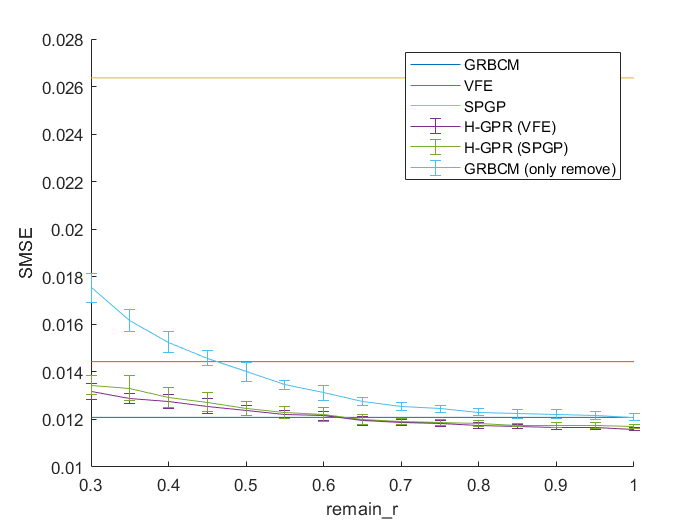

aamse = grbcm2_gr_smse(1:kti,:);
aamsll = grbcm2_gr_msll(1:kti,:);
mmse = mean(aamse);
mstd = std(aamse);
mmse_ro = mean(grbcm_gr_smse(1:kti,:));
mstd_ro = std(grbcm_gr_smse(1:kti,:));
mmse_sp = mean(grbcm2_spgp_gr_smse(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_smse(1:kti,:));

figure; hold on;
plot([min(grls), max(grls)], [grbcm0_smse,grbcm0_smse]);
plot([min(grls), max(grls)], [vfeSMSE_bl,vfeSMSE_bl]);
plot([min(grls), max(grls)], [spgpSMSE_bl,spgpSMSE_bl]);
errorbar(grls, mmse, mstd);
errorbar(grls, mmse_sp, mstd_sp);
errorbar(grls, mmse_ro, mstd_ro);
legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('remain\_r'); ylabel('SMSE');

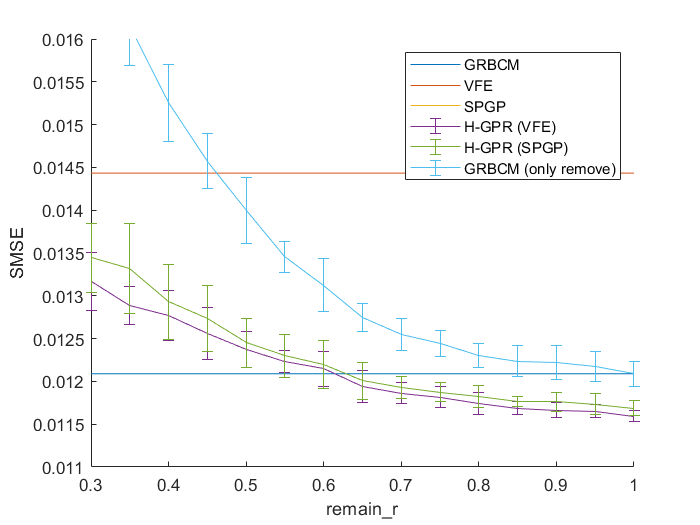

aamse = grbcm2_gr_smse(1:kti,:);
aamsll = grbcm2_gr_msll(1:kti,:);
mmse = mean(aamse);
mstd = std(aamse);
mmse_ro = mean(grbcm_gr_smse(1:kti,:));
mstd_ro = std(grbcm_gr_smse(1:kti,:));
mmse_sp = mean(grbcm2_spgp_gr_smse(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_smse(1:kti,:));

figure; hold on;
plot([min(grls), max(grls)], [grbcm0_smse,grbcm0_smse]);
plot([min(grls), max(grls)], [vfeSMSE_bl,vfeSMSE_bl]);
plot([min(grls), max(grls)], [spgpSMSE_bl,spgpSMSE_bl]);
errorbar(grls, mmse, mstd);
errorbar(grls, mmse_sp, mstd_sp);
errorbar(grls, mmse_ro, mstd_ro);
legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('remain\_r'); ylabel('SMSE');
ylim([0.011, 0.016]);

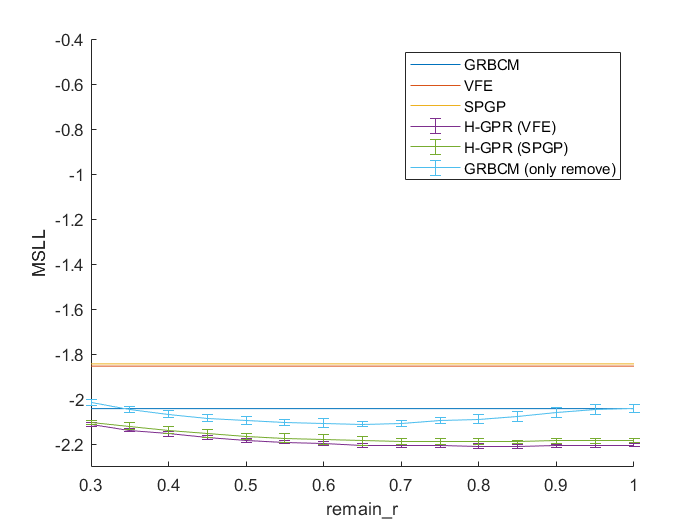

mmsll = mean(aamsll);
mstd = std(aamsll);
mmsll_ro = mean(grbcm_gr_msll(1:kti,:));
mstd_ro = std(grbcm_gr_msll(1:kti,:));
mmsll_sp = mean(grbcm2_spgp_gr_msll(1:kti,:));
mstd_sp = std(grbcm2_spgp_gr_msll(1:kti,:));
figure; hold on;
plot([min(grls), max(grls)], [grbcm0_msll,grbcm0_msll]);
plot([min(grls), max(grls)], [vfeMSLL_bl,vfeMSLL_bl]);
plot([min(grls), max(grls)], [spgpMSLL_bl,spgpMSLL_bl]);
errorbar(grls, mmsll, mstd);
errorbar(grls, mmsll_sp, mstd_sp);
errorbar(grls, mmsll_ro, mstd_ro);
legend('GRBCM', 'VFE', 'SPGP', 'H-GPR (VFE)', 'H-GPR (SPGP)', 'GRBCM (only remove)');
xlabel('remain\_r'); ylabel('MSLL');
ylim([-2.3, -0.4]);

fprintf('Best SMSE (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmse));

Best SMSE (GRBCM+VFE, dcs 150, ecs 150): 0.01159231


fprintf('Best MSLL (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmsll));

Best MSLL (GRBCM+VFE, dcs 150, ecs 150): -2.20840538



fprintf('Best SMSE (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmse_sp));

Best SMSE (GRBCM+SPGP, dcs 150, ecs 150): 0.01168647


fprintf('Best MSLL (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, min(mmsll_sp));

Best MSLL (GRBCM+SPGP, dcs 150, ecs 150): -2.18825519


## Experiment II: re-balancing sizes of dcs and ecs

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 50 ;
opts.xvec = xvec;
opts.yvec = yvec;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, []};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

Heuristically rebalancing GRBCM and VFE/SPGP budget based on validating performance.

Obtain results on the validation set.

% default partition
dcs_ecs_r = 0.5;
dcs = round(ttcs*dcs_ecs_r) % size of the communication set

dcs = 150

ecs = ttcs - dcs % size of other experts

ecs = 150


n_per = dcs ; % size of Dc
mn = round(n / ecs); % mn is the number of experts (normal)
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, mn,'MaxIter',km_iters);    

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = mn+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 1;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 

Optimizing hyps in training...
Linesearch      0;  Value 5.656439e+03
Linesearch      1;  Value 3.912485e+03
Linesearch      2;  Value 1.453360e+01
Linesearch      3;  Value -4.871853e+03
Linesearch      4;  Value -5.935522e+03
Linesearch      5;  Value -6.021155e+03
Linesearch      6;  Value -6.062374e+03
Linesearch      7;  Value -6.099711e+03
Linesearch      8;  Value -6.202108e+03
Linesearch      9;  Value -6.313987e+03
Linesearch     10;  Value -6.348283e+03
Linesearch     11;  Value -6.351989e+03
Linesearch     12;  Value -6.352783e+03
Linesearch     13;  Value -6.353207e+03
Linesearch     14;  Value -6.353433e+03
Linesearch     15;  Value -6.353554e+03
Linesearch     16;  Value -6.353573e+03
Linesearch     17;  Value -6.353573e+03
Linesearch     18;  Value -6.353573e+03
Linesearch     19;  Value -6.353573e+03
Linesearch     20;  Value -6.353573e+03
Linesearch     21;  Value -6.353573e+03
Linesearch     22;  Value -6.353573e+03
Linesearch     23;  Value -6.353573e+03
Linesearch  

opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_val,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_val, ori_yvec_val, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);

GRBCM (Dc size 150): MSE 0.01141714, SMSE 0.01154193, MSLL -2.07614533



g_opts.compute_hyp = 0;

% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com, :);
inffunc = @(varargin) infGaussLik(varargin{:}, struct('s', 0.0));
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
[vfe_hyp, tmp_nlzs] = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);

Function evaluation      0;  Value 9.713131e+04
Function evaluation     12;  Value 9.523192e+04
Function evaluation     14;  Value 9.461697e+04
Function evaluation     18;  Value 8.908681e+04
Function evaluation     19;  Value 8.818066e+04
Function evaluation     21;  Value 8.685544e+04
Function evaluation     23;  Value 8.595105e+04
Function evaluation     25;  Value 8.558632e+04
Function evaluation     28;  Value 8.459281e+04
Function evaluation     34;  Value 5.531429e+04
Function evaluation     36;  Value 4.157103e+04
Function evaluation     38;  Value 3.313305e+04
Function evaluation     40;  Value 2.675902e+04
Function evaluation     42;  Value 2.393547e+04
Function evaluation     44;  Value 2.228229e+04
Function evaluation     46;  Value 2.010133e+04
Function evaluation     48;  Value 1.898583e+04
Function evaluation     49;  Value 1.781364e+04
Function evaluation     51;  Value 1.678928e+04
Function evaluation     53;  Value 1.617900e+04
Function evaluation     55;  Value 1.576

vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_val);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE,vfeSMSE,vfeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_val, ori_yvec_val, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE', n_per, vfeMSE,vfeSMSE,vfeMSLL);

VFE (Dc size 150): MSE 0.01364978, SMSE 0.01379897, MSLL -1.86333239


% vfe0_smse_rec(ki) = vfeSMSE; vfe0_msll_rec(ki) = vfeMSLL;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
[tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_val,models,vfe_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_val, ori_yvec_val, tmu, ts2);
fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (VFE)', n_per, MSE,SMSE,MSLL);

GRBCM++ (VFE) (Dc size 150): 
MSE 0.01076750, SMSE 0.0109, MSLL -2.2371


sig_temp = 10;
dcs_ecs_r = sigmoid(-MSLL+grbcmMSLL, sig_temp)

dcs_ecs_r = 0.8334

dcs = round(ttcs*dcs_ecs_r)

dcs = 250

ecs = ttcs - dcs

ecs = 50

m = round(n / ecs)

m = 200

n_per = dcs ; % size of Dc
Indics = randperm(n) ;
I_com = Indics(1:n_per) ; % randomly select communication set
[idx, C] = kmeans(xvec, m,'MaxIter',km_iters);    

% hyp.cov = log([ones(d,1)*ell;sf2]); hyp.lik = log(sn2); hyp.mean = [];    
opts.numOptFC = 30 ;
opts.Ms = m+1;
opts.xvec = xvec;
opts.yvec = yvec;
opts.induce_size = dcs;
opts.grbcm_baseline = 0;
opts.global_index = ones(n,1);
opts.I_com = I_com;
% opts.inffunc = @infGaussLik; opts.meanfunc = meanfunc; opts.likfunc = likfunc;
opts.covfunc = covfunc;
covfuncF = {@apxSparse, {opts.covfunc}, xvec(I_com,:)};
opts.covfuncF = covfuncF;
opts.compute_hyp = 0;

g_opts = opts;
g_opts.compute_hyp = 0;
g_opts.grbcm_baseline = 1;
g_opts.global_index = ones(n,1);
g_models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,g_opts); 
opts.hyp = g_models{1}.hyp;
g_opts.hyp = g_models{1}.hyp;
[tmu,ts2, ~] =  aggregation_predict(xvec_test,g_models,'GRBCM', 1, g_opts);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[grbcmMSE,grbcmSMSE,grbcmMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'GRBCM', n_per, grbcmMSE,grbcmSMSE,grbcmMSLL);

GRBCM (Dc size 250): MSE 0.01157380, SMSE 0.01214926, MSLL -2.14087613


% grbcm0_smse_rec(ki) = grbcmSMSE; grbcm0_msll_rec(ki) = grbcmMSLL;
g_opts.compute_hyp = 0;

% % VFE Baseline
vfe_opts = opts;
vfe_opts.induce_type = 'VFE_opt';
xu = xvec(I_com, :);
vfe_hyp = opts.hyp;
vfe_hyp.xu = xu;
vfe_hyp = minimize(vfe_hyp,@sp_gp,-vfe_opts.induce_step,inffunc,meanfunc,covfuncF,likfunc,xvec,yvec);

Function evaluation      0;  Value 4.095793e+03
Function evaluation      7;  Value 4.044684e+03
Function evaluation     12;  Value 2.153300e+03
Function evaluation     16;  Value -1.446170e+03
Function evaluation     20;  Value -2.178237e+03
Function evaluation     21;  Value -3.626735e+03
Function evaluation     23;  Value -4.443031e+03
Function evaluation     25;  Value -4.830984e+03
Function evaluation     27;  Value -5.061232e+03
Function evaluation     29;  Value -5.239347e+03
Function evaluation     31;  Value -5.381591e+03
Function evaluation     33;  Value -5.490788e+03
Function evaluation     35;  Value -5.562676e+03
Function evaluation     37;  Value -5.605160e+03
Function evaluation     39;  Value -5.639820e+03
Function evaluation     41;  Value -5.671277e+03
Function evaluation     43;  Value -5.691736e+03
Function evaluation     45;  Value -5.707315e+03
Function evaluation     46;  Value -5.721022e+03
Function evaluation     48;  Value -5.734093e+03
Function evaluation    

vfe_opts.hyp = opts.hyp;
vfe_opts.xu = vfe_hyp.xu;
vfe_opts.inffunc = @infGaussLik; vfe_opts.meanfunc = meanfunc; vfe_opts.covfuncF = covfuncF; vfe_opts.likfunc = likfunc;
vfe_opts.covfunc = covfunc;
[tmu, ts2] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, xvec_test);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[vfeMSE,vfeSMSE,vfeMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'VFE baseline', n_per, vfeMSE,vfeSMSE,vfeMSLL);

VFE baseline (Dc size 250): MSE 0.01120477, SMSE 0.01176188, MSLL -2.20525114


% vfe0_smse_rec(ki) = vfeSMSE; vfe0_msll_rec(ki) = vfeMSLL;
[yu, su] = gp(vfe_hyp, @infGaussLik, meanfunc, covfuncF, likfunc, xvec, yvec, vfe_opts.xu);
vfe_opts.yu = yu; vfe_opts.su = su; 

sp_opts = opts;
sp_opts.induce_type = 'SPGP_opt';
hyp_init(1:d,1) = -2*opts.hyp.cov(1:d);
hyp_init(d+1,1) = 2*opts.hyp.cov(d+1);
hyp_init(d+2,1) = 2*opts.hyp.lik;

sp_opts.induce_size = dcs;
xu = xvec(I_com, :);
w_init = [reshape(xu,sp_opts.induce_size*d,1);hyp_init];
[w,f] = minimize(w_init,'spgp_lik_nohyp',-sp_opts.induce_step,yvec,xvec,sp_opts.induce_size);

Function evaluation      0;  Value -5.763649e+03
Function evaluation     10;  Value -6.000609e+03
Function evaluation     11;  Value -6.253401e+03
Function evaluation     12;  Value -6.523034e+03
Function evaluation     13;  Value -6.759506e+03
Function evaluation     18;  Value -6.774817e+03
Function evaluation     23;  Value -6.968110e+03
Function evaluation     25;  Value -7.084927e+03
Function evaluation     27;  Value -7.188545e+03
Function evaluation     31;  Value -7.231472e+03
Function evaluation     32;  Value -7.256834e+03
Function evaluation     33;  Value -7.290383e+03
Function evaluation     36;  Value -7.304290e+03
Function evaluation     39;  Value -7.323292e+03
Function evaluation     41;  Value -7.337716e+03
Function evaluation     43;  Value -7.346195e+03
Function evaluation     45;  Value -7.357249e+03
Function evaluation     46;  Value -7.367864e+03
Function evaluation     48;  Value -7.377567e+03
Function evaluation     50;  Value -7.384789e+03
Function evaluation 

xb = reshape(w(1:sp_opts.induce_size*d,1),sp_opts.induce_size,d);
sp_opts.xu = xb;
sp_opts.sp_hyp = w(sp_opts.induce_size*d+1:end,1);
sp_opts.hyp = opts.hyp;

[tmu,ts2] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,xvec_test,sp_opts.sp_hyp);
if ynorm==1
    tmu = tmu * norm_fstd + norm_fmean;
    ts2 = ts2 * norm_fstd^2;
end
[spgpMSE,spgpSMSE,spgpMSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
fprintf('%s (Dc size %d): MSE %6.8f, SMSE %6.8f, MSLL %6.8f\r\n', 'SPSG baseline', n_per, spgpMSE,spgpSMSE,spgpMSLL);

SPSG baseline (Dc size 250): MSE 0.01127628, SMSE 0.01183695, MSLL -2.18665098


% spgp0_smse_rec(ki) = spgpSMSE; spgp0_msll_rec(ki) = spgpMSLL;
[yu,su] = spgp_pred(sp_opts.yvec,sp_opts.xvec,sp_opts.xu,sp_opts.xu,sp_opts.sp_hyp);
sp_opts.yu = yu; sp_opts.su = su;

[~, minidx] = min(mmsll);
best_msll_gr = grls(minidx)

best_msll_gr = 0.8500


[~, minidx] = min(mmse);
best_smse_gr = grls(minidx)

best_smse_gr = 1

kti = 1;
rb_vfe_msll = zeros(kti, 1);
rb_vfe_smse = zeros(kti, 1);

rb_sp_msll = zeros(kti, 1);
rb_sp_smse = zeros(kti, 1);

for ki=1:kti
    gr = best_msll_gr
    crk = rk;
    crk(I_com) = -1e10;
    [~, crk_idx] = sort(crk, 'descend');
    rn = round(n*gr);
    global_index = zeros(n,1);
    global_index(crk_idx(1:rn)) = 1; % select remaining data according to the importance
       
    vfe_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (VFE)', n_per, MSE,SMSE,MSLL);
    rb_vfe_msll(ki) = MSLL;
    
    sp_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (SPGP)', n_per, MSE,SMSE,MSLL);
    rb_sp_msll(ki) = MSLL;
    
  
    %%%%========================================================================%%
    
    gr = best_smse_gr
    crk = rk;
    crk(I_com) = -1e10;
    [~, crk_idx] = sort(crk, 'descend');
    rn = round(n*gr);
    global_index = zeros(n,1);
    global_index(crk_idx(1:rn)) = 1; % select remaining data according to the importance
       
    vfe_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,vfe_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,vfe_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (VFE)', n_per, MSE,SMSE,MSLL);
    rb_vfe_smse(ki) = SMSE;
    
    sp_opts.global_index = global_index;
    models = aggregation_train_GRBCM_VS_apx(xvec,yvec,idx,sp_opts); % use hyp of vfe
    [tmu,ts2] =  aggregation_predict_GRBCM_VS_apx(xvec_test,models,sp_opts);
    if ynorm==1
        tmu = tmu * norm_fstd + norm_fmean;
        ts2 = ts2 * norm_fstd^2;
    end
    [MSE,SMSE,MSLL] = evaluate2(ori_xvec, ori_yvec, ori_xvec_test, ori_yvec_test, tmu, ts2);
    fprintf('%s (Dc size %d): \r\nMSE %6.8f, SMSE %6.4f, MSLL %6.4f\r\n', 'GRBCM++ (SPGP)', n_per, MSE,SMSE,MSLL);
    rb_sp_smse(ki) = SMSE;
end

gr = 0.8500

GRBCM++ (VFE) (Dc size 250): 
MSE 0.01097973, SMSE 0.0115, MSLL -2.2169


GRBCM++ (SPGP) (Dc size 250): 
MSE 0.01095480, SMSE 0.0115, MSLL -2.2184


gr = 1

GRBCM++ (VFE) (Dc size 250): 
MSE 0.01089448, SMSE 0.0114, MSLL -2.2233


GRBCM++ (SPGP) (Dc size 250): 
MSE 0.01088845, SMSE 0.0114, MSLL -2.2230


fprintf('Best SMSE (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, mean(rb_vfe_smse));

Best SMSE (GRBCM+VFE, dcs 250, ecs 50): 0.01143616


fprintf('Best MSLL (GRBCM+VFE, dcs %d, ecs %d): %6.8f\n', dcs, ecs, mean(rb_vfe_msll));

Best MSLL (GRBCM+VFE, dcs 250, ecs 50): -2.21693520



fprintf('Best SMSE (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, mean(rb_sp_smse));

Best SMSE (GRBCM+SPGP, dcs 250, ecs 50): 0.01142983


fprintf('Best MSLL (GRBCM+SPGP, dcs %d, ecs %d): %6.8f\n', dcs, ecs, mean(rb_sp_msll));

Best MSLL (GRBCM+SPGP, dcs 250, ecs 50): -2.21840471
